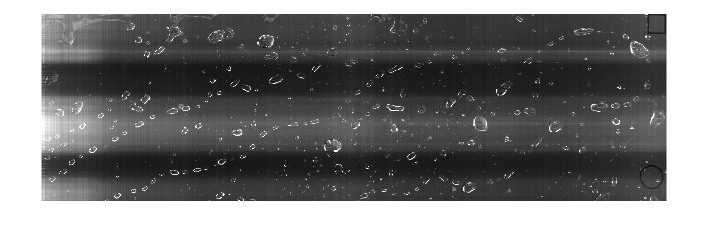

% Get image for analyzing
img_source = im2gray(imread('_IMAG0003.JPG'));
imshow(img_source)

relImg = double(img_source)./256;

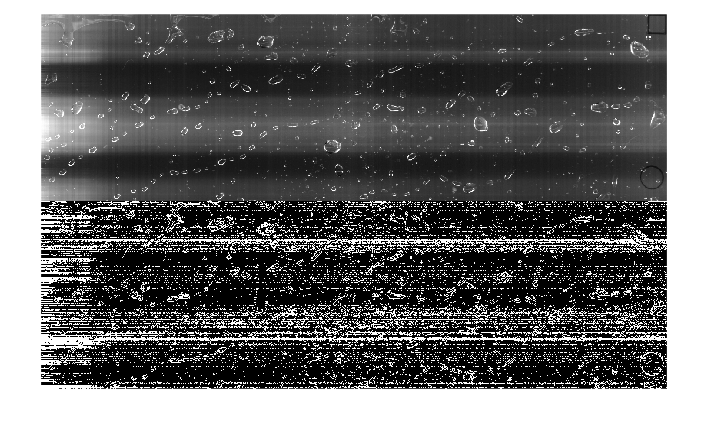

% Sobel filtering
H = fspecial('sobel');
img_sobel = filter2(H,img_source);
montage({img_source, img_sobel},'Size', [2 1]);

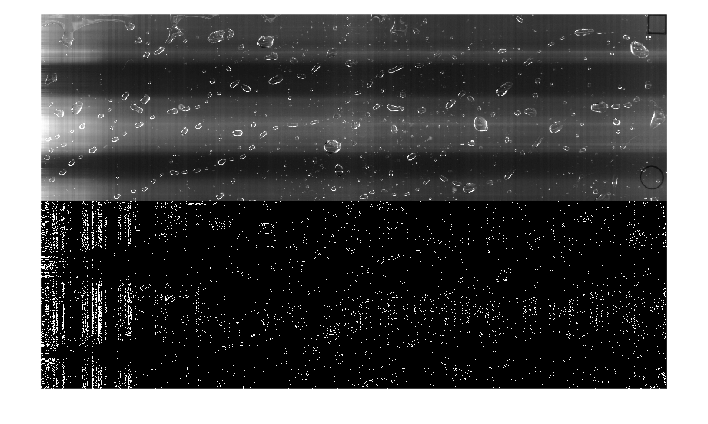

bw = edge(img_source,'log');
montage({img_source, bw},'Size', [2 1]);